# BME3053C Final Project

ECG Classification Model

Group Members: Daniil Fortuna, Kristen Rifenberg, Kathleen Trang

Course: BME 3053C Computer Applications for BME

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: fortuna.da@ufl.edu, krifenberg@ufl.edu, ktrang@ufl.edu

Dec 5, 2023

If you want to generate a set of randomized test images for the model to classify, run the entire program.

If you only want to classify one signal, run the singleClassification(trainedNN) section. This will prompt you to select a .mat signal.

CHF_directory = dir('CHF');
NSR_directory = dir('NSR');
CHF_folder = CHF_directory(1).folder;
NSR_folder = NSR_directory(1).folder;

CHF_raw_filenames = cell(1, 15);
for i = 3:2:length(CHF_directory)
    k = (i-1)/2;
    CHF_raw_filenames(k) = {strcat(CHF_folder,'\',CHF_directory(i).name)};
end
CHF_filenames = erase(CHF_raw_filenames, '.info');

NSR_raw_filenames = cell(1, 18);
for i = 3:2:length(NSR_directory)
    k = (i-1)/2;
    NSR_raw_filenames(k) = {strcat(NSR_folder,'\',NSR_directory(i).name)};
end
NSR_filenames = erase(NSR_raw_filenames, '.info');

%CHF
CHF_data = zeros(15,1000000);
CHF_data = adaptedPhysioRetrieval(CHF_data,CHF_filenames);

%NSR
NSR_data = zeros(18,1000000);
NSR_data = adaptedPhysioRetrieval(NSR_data,NSR_filenames);

if ~isfolder('Testing')
    mkdir('Testing');
end
if ~isfolder('Testing\CHF')
    mkdir('Testing\CHF');
end
if ~isfolder('Testing\NSR')
    mkdir('Testing\NSR');
end
generateSnapshots(CHF_data,NSR_data,'Testing');

testImg = imageDatastore("Testing","IncludeSubfolders",true,"LabelSource","foldernames");
disp("Number of testing images: "+num2str(numel(testImg.Files)))

Number of testing images: 99


load('trainedModel.mat','trainedNN');

[YPred,~] = classify(trainedNN,testImg);
accuracy = mean(YPred==testImg.Labels);
disp("Trained Model Accuracy: "+num2str(100*accuracy)+"%")

Trained Model Accuracy: 88.8889%


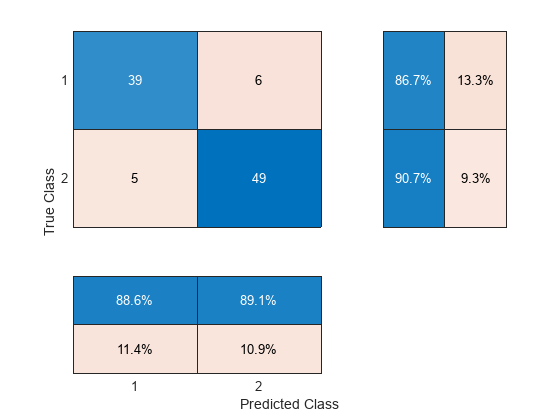

cMat = confusionmat(testImg.Labels,YPred);
figure
confusionchart(cMat, 'RowSummary','row-normalized', 'ColumnSummary','column-normalized');

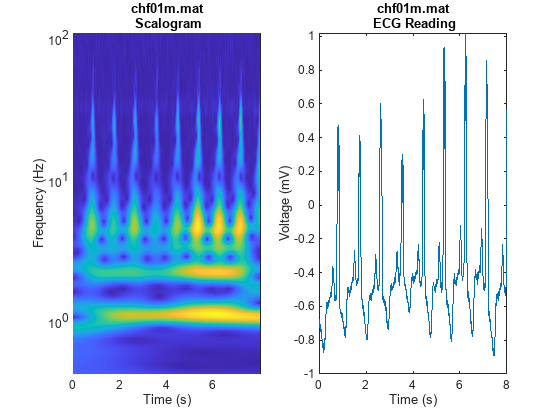

     chf01m.mat      CHF 



singleClassification(trainedNN);

This function was adapted from the following: https://www.mathworks.com/help/deeplearning/ug/classify-time-series-using-wavelet-analysis-and-deep-learning.html#ECGAndDeepLearningExample-9

function helperCreateRGBfromTF(ECGData,parentFolder,childFolder,Fs,label)

imageRoot = fullfile(parentFolder,childFolder);

data = ECGData;

[~,signalLength] = size(data);

fb = cwtfilterbank(SignalLength=signalLength,SamplingFrequency=Fs,VoicesPerOctave=12);
r = size(data,1);

for ii = 1:r
    cfs = abs(fb.wt(data(ii,:)));
    im = ind2rgb(round(rescale(cfs,0,255)),jet(128));
    
    imgLoc = fullfile(imageRoot);
    imFileName = char(label)+"_"+num2str(ii)+".jpg";
    imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName));
end
end

generateSnapshots is a function that takes a parent directory and CHF and NSR data arrays and creates [224 224 3] RGB scalograms from randomized snapshots (8-second segments of a signal).

function generateSnapshots(CHF_data, NSR_data, parentDir)

if ~isfolder(fullfile(parentDir,'CHF'))
    mkdir(fullfile(parentDir,'CHF'));
end

if ~isfolder(fullfile(parentDir,'NSR'))
    mkdir(fullfile(parentDir,'NSR'));
end

%CHF
CHF_data_snapshots = zeros(45,2000);
for dat = 1:15
    for num = 1:3

        random = randi([1, 1000000-1999]);
        CHF_snapshot = CHF_data(dat, random:(random+1999));
        CHF_data_snapshots(num+3*(dat-1), :) = CHF_snapshot;

    end
end

%NSR
NSR_data_snapshots = zeros(54,1024);
for dat = 1:18
    for num = 1:3

        random = randi([1, 1000000-1023]);
        NSR_snapshot = NSR_data(dat, random:(random+1023));
        NSR_data_snapshots(num+3*(dat-1), :) = NSR_snapshot;

    end
end

%{
%CHF Visualization
t = (0:2000-1)/250;
for CHF = 1:height(CHF_data_snapshots)
    plotScalogram(CHF_data_snapshots,'CHF',128,1024);
end

%NSR Visualization
t = (0:1024-1)/128;
for NSR = 1:height(NSR_data_snapshots)
    plotScalogram(NSR_data_snapshots,'NSR',128,1024);
end
%}

helperCreateRGBfromTF(CHF_data_snapshots,parentDir,'CHF',250,'CHF');
helperCreateRGBfromTF(NSR_data_snapshots,parentDir,'NSR',128,'NSR');
end

adaptedPhysioRetrieval is adapted from "plotATM.m" by PhysioNet researchers O. Abdala and James Hislop. The files needed for this section and the original function code can be produced by the PhysioBank ATM at [http://physionet.org/cgi-bin/ATM](http://physionet.org/cgi-bin/ATM). 

Input: empty array the length of readings to be taken from each ECG file and list of ECG filenames

Output: filled array of ECG data points

function[ECG_data] = adaptedPhysioRetrieval(ECG_data,ECG_filenames)

for k=1:length(ECG_filenames)
    if ischar(ECG_filenames)
        Name = ECG_filenames;
    else
        Name = ECG_filenames{k};
    end
    infoName = strcat(Name, '.info');
    matName = strcat(Name, '.mat');
    load(matName);
    fid = fopen(infoName, 'rt');
    fgetl(fid);
    fgetl(fid);
    fgetl(fid);
    [freqint] = sscanf(fgetl(fid), 'Sampling frequency: %f Hz  Sampling interval: %f sec');
    interval = freqint(2);
    fgetl(fid);
    
    for i = 1:size(val, 1)
        [row(i), signal(i), gain(i), base(i), units(i)]=strread(fgetl(fid),'%d%s%f%f%s','delimiter','\t');
    end
    
    fclose(fid);
    val(val==-32768) = NaN;
    
    for i = 1:size(val, 1)
        val(i, :) = (val(i, :) - base(i)) / gain(i);
    end
    
    x = (1:size(val, 2)) * interval;

    ECG_data(k,:) = val(1,:);

end
end

plotScalogram plots a scalogram and the waveform of a signal.

Input: 1D array containing a snapshot signal (length varies due to Fs), signal filename, Fs = sampling frequency, s = # of readings in the snapshot (length of the signal snapshot)

output: fb = continuous wavelet transform filter bank generated for Fs and s at 12 voices per octave

function[fb] = plotScalogram(ECG_data_snapshot,ECG_filename,Fs,s)
t = (0:s-1)/Fs;
fb = cwtfilterbank(SignalLength=s,SamplingFrequency=Fs,VoicesPerOctave=12);
sig = ECG_data_snapshot;
[cfs, frq] = wt(fb,sig);
    
figure
subplot(1,2,1)
pcolor(t,frq,abs(cfs))
set(gca,"yscale","log")
shading interp
axis tight
title([ECG_filename " Scalogram"])
xlabel("Time (s)")
ylabel("Frequency (Hz)")

subplot(1,2,2)
plot(t, ECG_data_snapshot)
title([ECG_filename " ECG Reading"])
xlabel("Time (s)")
ylabel("Voltage (mV)")
end

singleClassification will allow the user to select one .mat file to be visualized and subsequently classified.

input: a neural network

function singleClassification(NN)
    [file, path] = uigetfile({'*.mat', 'Image Files'}, 'Select a .mat ECG');
    while isequal(file, 0)
        disp('No image selected. Retry...');
        [file, path] = uigetfile({'*.mat', 'Image Files'}, 'Select a .mat ECG');
    end

    load(fullfile(path,file));
    ECG_data = zeros(1,1000000);
    filename = fullfile(path,file);
    filename = filename(1:length(filename)-4);
    ECG_data = adaptedPhysioRetrieval(ECG_data,filename);
    ECG_data = ECG_data(1,:);

    if file(1)=='c'
        s = 2000;
        Fs = 250;
    else
        s = 1024;
        Fs = 128;
    end
    random = randi([1, 1000000-s-1]);
    ECG_snapshot = ECG_data(random:(random+s-1));
    fb = plotScalogram(ECG_snapshot,file,Fs,s);
    cfs = abs(fb.wt(ECG_snapshot));
    ECG_Scalogram = ind2rgb(round(rescale(cfs,0,255)),jet(128));
    imwrite(imresize(ECG_Scalogram,[224 224]),'singleClassificationImg.jpg');
    prediction = classify(NN, imread('singleClassificationImg.jpg'));
    disp([file prediction]);
end

trainModelFromGN defines the options required to train the GoogLeNet generalist network on scalograms, returning a trained neural network.

input: training imageDatastore, validation imageDatastore

output: DAGNetwork (neural network)

function[NN] = trainModelFromGN(trainingImg, validImg)
net = googlenet;
lgraph = layerGraph(net);

%{
%confirming NN image input size
numberOfLayers = numel(lgraph.Layers);
figure("Units","normalized","Position",[0.1 0.1 0.8 0.8])
plot(lgraph)
title("GoogLeNet Layer Graph: "+num2str(numberOfLayers)+" Layers")
lgraph.Layers(1)
%}

%see last 5 layers of the NN
%lgraph.Layers(end-4:end)
% dropout layer controls overfitting by taking away neurons
newDropoutLayer = dropoutLayer(0.6,"Name","new_Dropout");
lgraph = replaceLayer(lgraph,"pool5-drop_7x7_s1",newDropoutLayer);
numClasses = numel(categories(trainingImg.Labels));
% everything connects to 2 classifications, learning and bias set higher to
% learn faster
newConnectedLayer = fullyConnectedLayer(numClasses,"Name","new_fc","WeightLearnRateFactor",5,"BiasLearnRateFactor",5);
lgraph = replaceLayer(lgraph,"loss3-classifier",newConnectedLayer);
% making a clean output layer
newClassLayer = classificationLayer("Name","new_classoutput");
lgraph = replaceLayer(lgraph,"output",newClassLayer);
%lgraph.Layers(end-4:end)

options = trainingOptions("sgdm", ...
    MiniBatchSize=10, ...
    MaxEpochs=20, ...
    InitialLearnRate=1e-5, ...
    ValidationData=validImg, ...
    ValidationFrequency=7, ...
    Verbose=1, ...
    Shuffle='every-epoch', ...
    GradientThreshold=2, ...
    Plots="training-progress");
NN = trainNetwork(trainingImg,lgraph,options);
end